clc
clear
close all

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current  working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model 



par = model2.setup; % Set parameters.
par = model2.gen_grids(par); % Generate the state space.

t = cputime;
sol = solve2.lc(par); % Solve the model using Value Function Iteration.

------------Solving the Life Cycle Model.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 4880.7031 seconds.


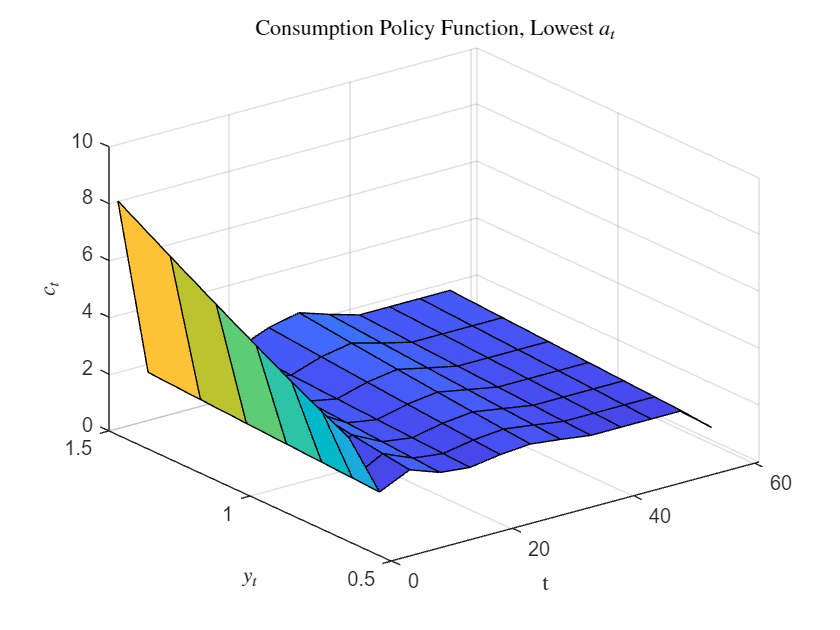

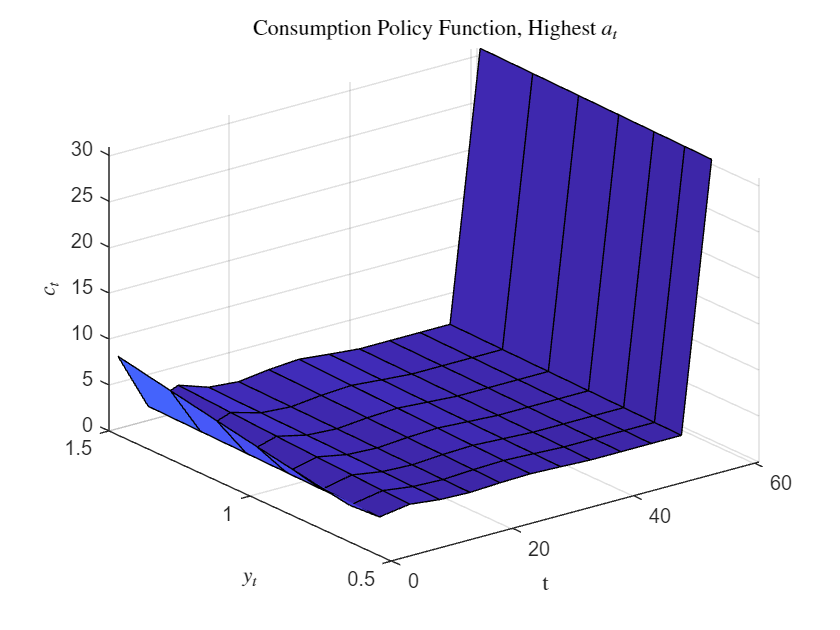

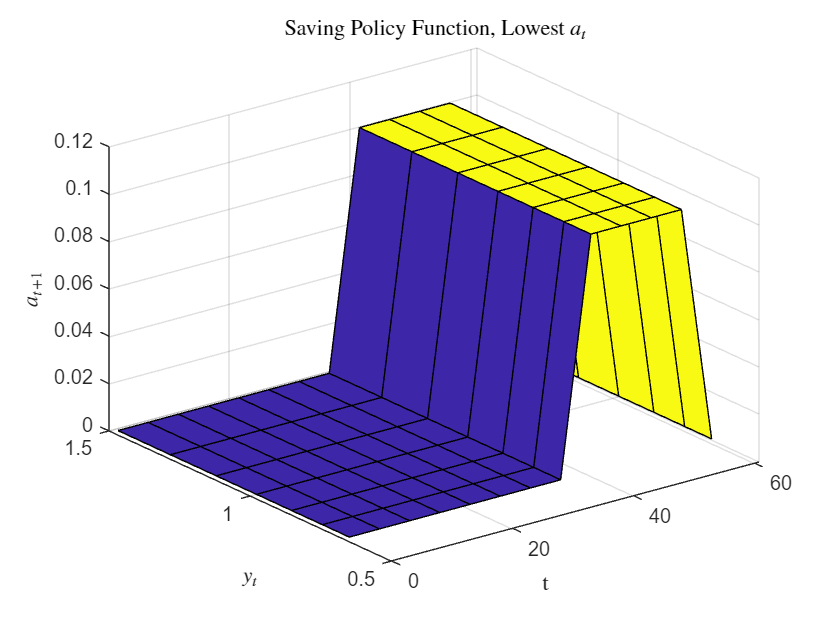

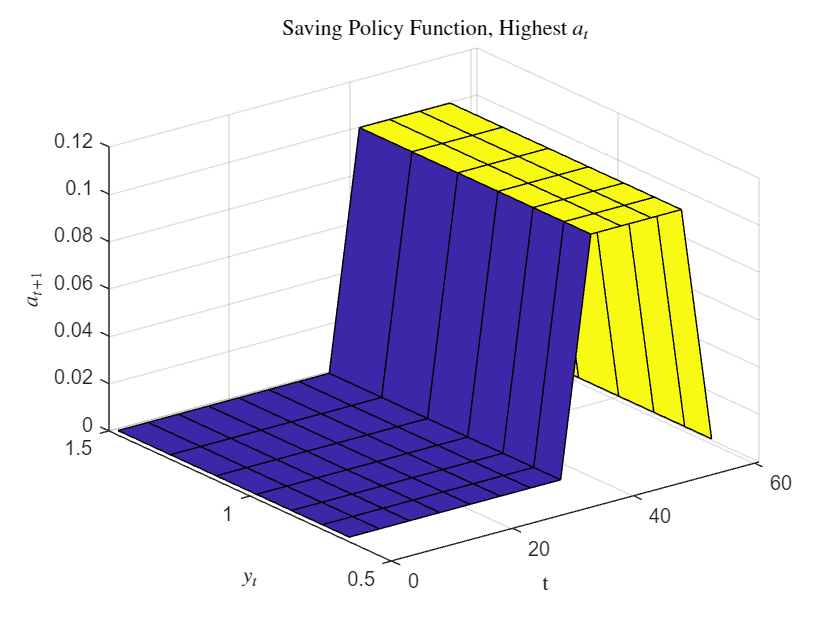

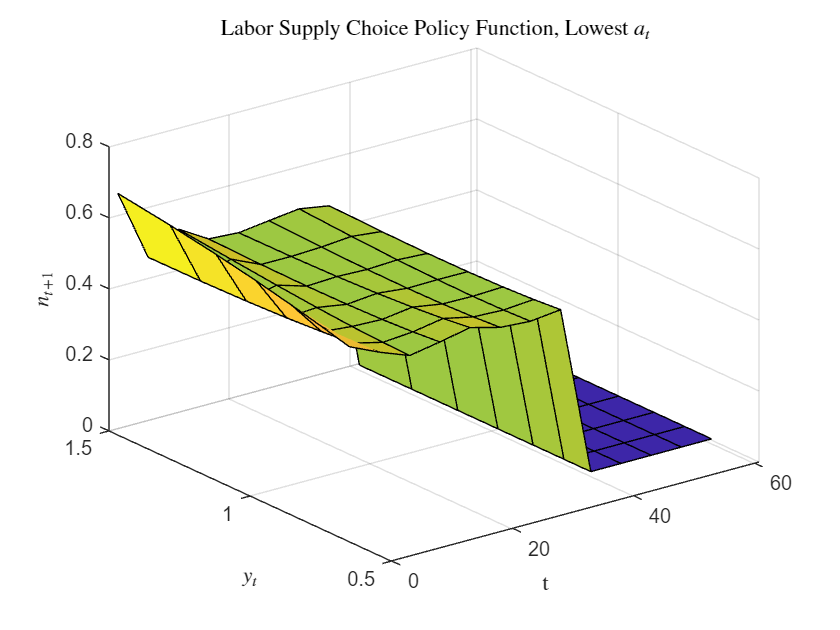

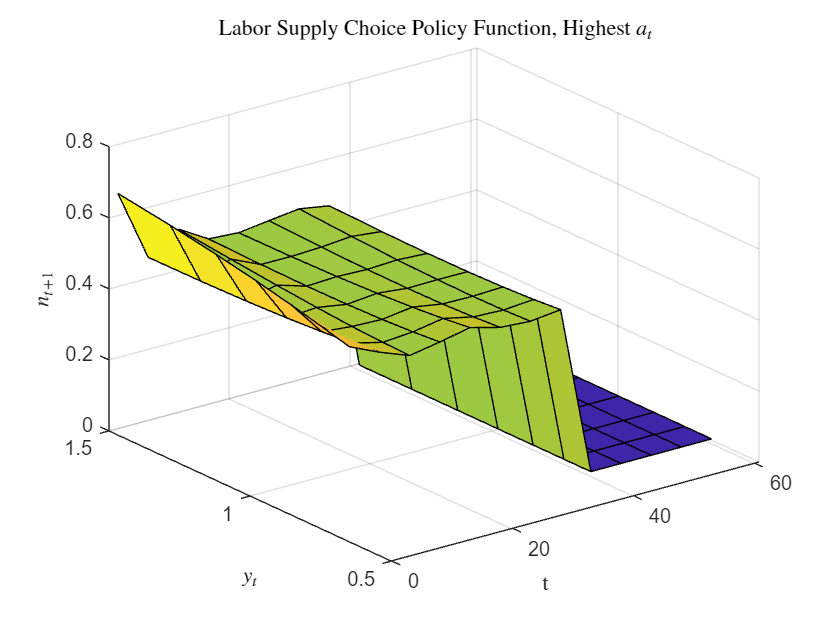

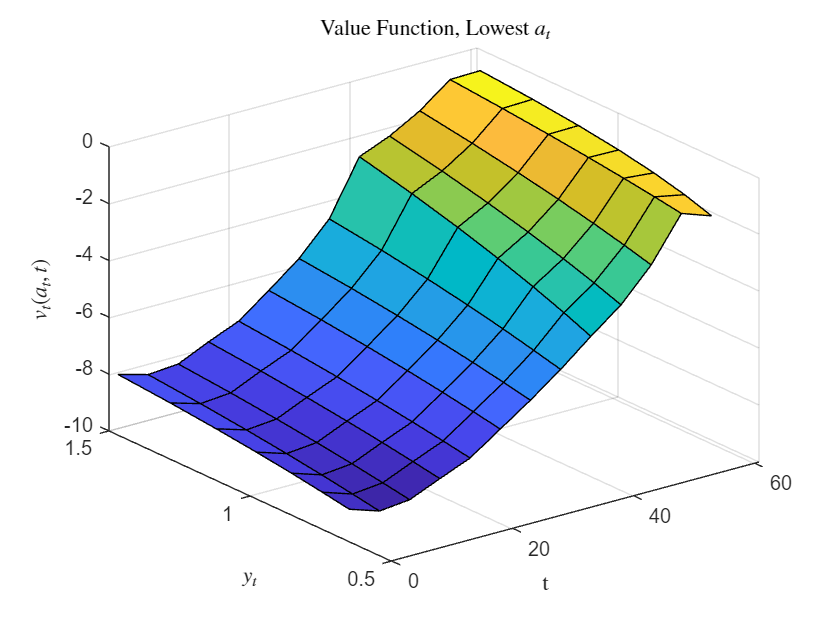

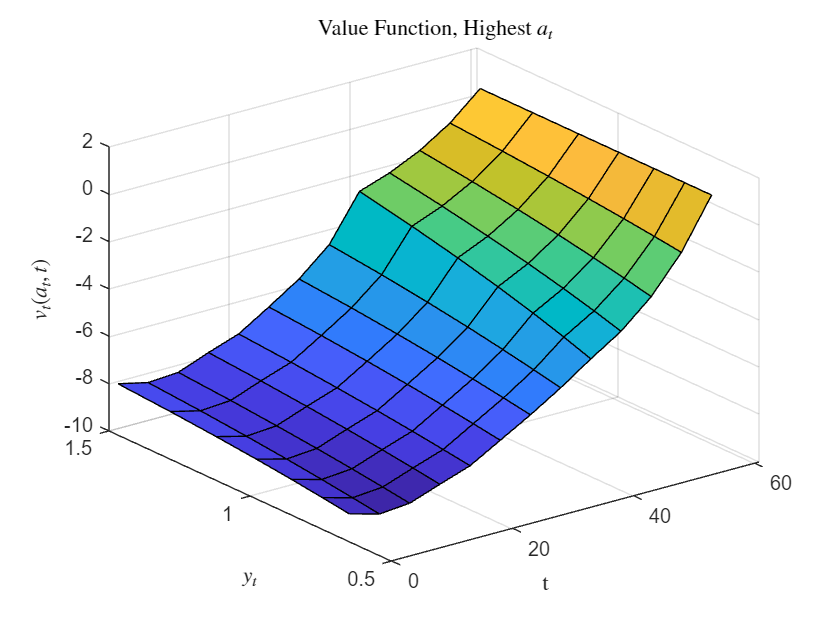

sim = simulate2.lc(par,sol); % Simulate the model.
my_graph2.plot_policy(par,sol,sim) % Plot the model functions and time series.